# Find the Path (Avoiding enemy robots)

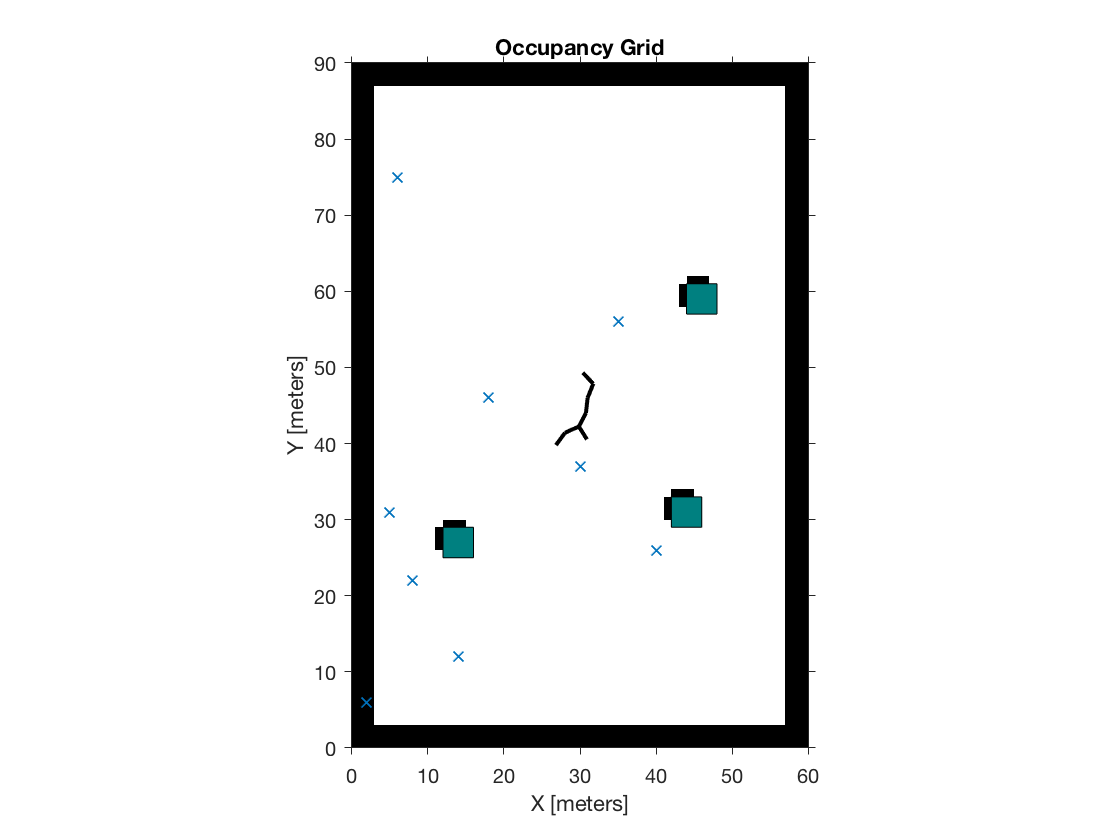

curPose = Pose(0,0,0,0,0);
destPose = Pose(2,2.2,0,0,0);

obs1 = Pose(1.3,1.3,0,0,0);
obs2 = Pose(-1.7,1.7,0,0,0);
obs3 = Pose(1.5,-1.5,0,0,0);
obstacles = {obs1, obs2, obs3};

waypoints = findWayPoints(curPose, destPose, obstacles);

grid on;

## Find the correct trajectories for the pose actions

speed = 0.01; % m/s
poseActionList = wayPointsToPoseActionList(waypoints, speed);
trajectory = run(poseActionList);